clear; clc;
addpath('/MATLAB Drive/Research/SLS_K_realization/structured_implementation/hyma code')

Our ultimate goal is to go from structured transfer matrices $\Phi^x$ and $\Phi^u$ (what I was previously calling $R$ and $L$ respectively) and partitions of $x$ and $u$ to a structured realization of $K$. The pipeline and our progress so far is shown below.

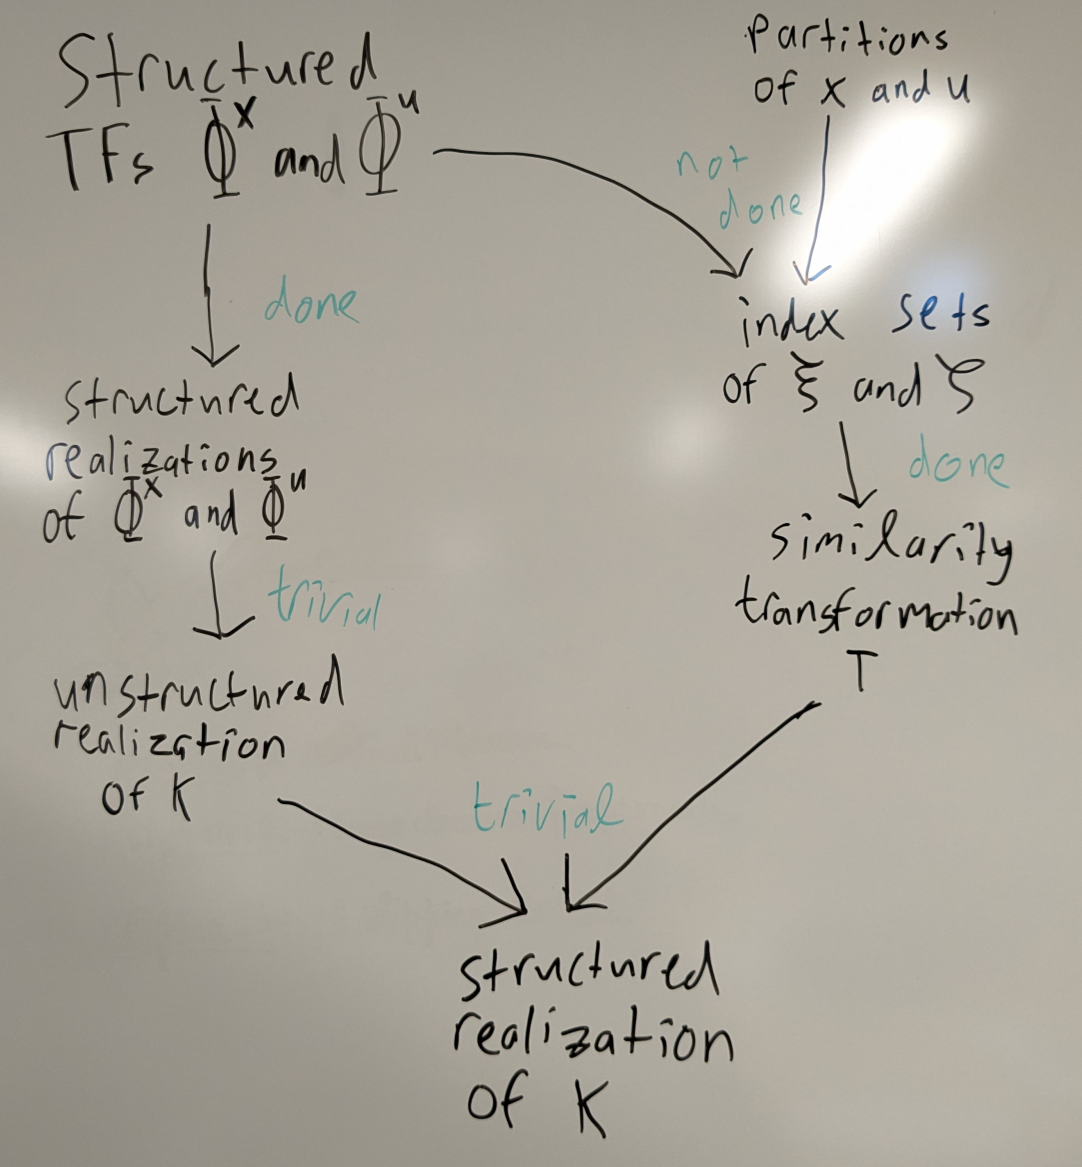

The only nontrivial step left is to generate the index sets of $\xi$ and $\zeta$ (the internal states of $\Phi^x$ and $\Phi^u$ respectively).

I've implemented code to do this that I'll demo in this script.

As an example, consider a plant $P$ comprised of three subsystems $P_1$, $P_2$ and $P_3$. The interactions between the plant subsystems and the controller is

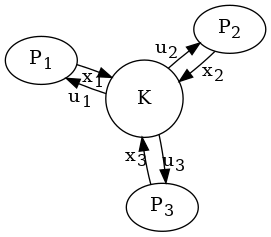

For this example, let the control effort dimensions be


$$u_1\in\mathbb{R}^2$$



$$u_2\in\mathbb{R}^1$$



$$u_3\in\mathbb{R}^2$$


Let the state dimensions be:


$$x_1\in\mathbb{R}^1$$



$$x_2\in\mathbb{R}^2$$



$$x_3\in\mathbb{R}^3$$


Let $\mathcal{I}_x$ be defined as the tuple contatining block sizes of the plant's states and $\mathcal{I}_u$ be the tuple containing the block sizes of the control effort. For this example $\mathcal{I}_x = (1,2,3)$ and $\mathcal{I}_u=(2,1,2)$. $\mathcal{I}_x$ and $\mathcal{I}_u$ are what I refer to in the flow chart as the partitions of $x$ and $u$.

$\Phi^u$ will have block rows of size $\mathcal{I}_u$ and block columns of size $\mathcal{I}_x$.


$$\Phi^u(s)=\left[\begin{array}{c|cc|ccc}
        \Phi^u_{11}(s)&\Phi^u_{12}(s)&\Phi^u_{13}(s)&\Phi^u_{14}(s)&\Phi^u_{15}(s)&\Phi^u_{16}(s)\\
        \Phi^u_{21}(s)&\Phi^u_{22}(s)&\Phi^u_{23}(s)&\Phi^u_{24}(s)&\Phi^u_{25}(s)&\Phi^u_{26}(s)\\
        \hline
        \Phi^u_{31}(s)&\Phi^u_{32}(s)&\Phi^u_{33}(s)&\Phi^u_{34}(s)&\Phi^u_{35}(s)&\Phi^u_{36}(s)\\
        \hline
        \Phi^u_{41}(s)&\Phi^u_{42}(s)&\Phi^u_{43}(s)&\Phi^u_{44}(s)&\Phi^u_{45}(s)&\Phi^u_{46}(s)\\
        \Phi^u_{51}(s)&\Phi^u_{52}(s)&\Phi^u_{53}(s)&\Phi^u_{54}(s)&\Phi^u_{55}(s)&\Phi^u_{56}(s)\\
    \end{array}\right]$$


$\Phi^x$ will have block row and column sizes of $\mathcal{I}_x$. 


$$\Phi^x=\left[\begin{array}{c|cc|ccc}
        \Phi^x_{11}(s)&\Phi^x_{12}(s)&\Phi^x_{13}(s)&\Phi^x_{14}(s)&\Phi^x_{15}(s)&\Phi^x_{16}(s)\\
        \hline
        \Phi^x_{21}(s)&\Phi^x_{22}(s)&\Phi^x_{23}(s)&\Phi^x_{24}(s)&\Phi^x_{25}(s)&\Phi^x_{26}(s)\\
        \Phi^x_{31}(s)&\Phi^x_{32}(s)&\Phi^x_{33}(s)&\Phi^x_{34}(s)&\Phi^x_{35}(s)&\Phi^x_{36}(s)\\
        \hline
        \Phi^x_{41}(s)&\Phi^x_{42}(s)&\Phi^x_{43}(s)&\Phi^x_{44}(s)&\Phi^x_{45}(s)&\Phi^x_{46}(s)\\
        \Phi^x_{51}(s)&\Phi^x_{52}(s)&\Phi^x_{53}(s)&\Phi^x_{54}(s)&\Phi^x_{55}(s)&\Phi^x_{56}(s)\\
        \Phi^x_{61}(s)&\Phi^x_{62}(s)&\Phi^x_{63}(s)&\Phi^x_{64}(s)&\Phi^x_{65}(s)&\Phi^x_{66}(s)
    \end{array}\right]$$


Create the variables that store the partitions:

partition_x = [1,2,3];
partition_u = [2,1,2];

Let $K$ be a distributed controller with subcontroller communication structure given by


$$\mathcal{A}=\left[\begin{array}{ccc} 1&1&1\\0&1&1\\0&0&1\end{array}\right]$$


Create some arbitrary $\Phi^x$ and $\Phi^u$ with the correct sizes which obey the communication structure.

h0 = tf(0,1); h1 = tf([1],[1 1]); h2 = tf([1],[1 1 1]); h3 = tf([1],[1,1,1,1]);

Phiu = [h1,h2,h3,h1,h2,h3;
        h1,h2,h3,h1,h2,h3;
        h0,h1,h2,h3,h2,h1;
        h0,h0,h0,h1,h2,h3;
        h0,h0,h0,h1,h2,h3];
Phix = [h1,h2,h3,h1,h2,h3;
        h0,h1,h2,h3,h1,h2;
        h0,h1,h2,h3,h1,h2;
        h0,h0,h0,h1,h2,h3;
        h0,h0,h0,h1,h2,h3;
        h0,h0,h0,h1,h2,h3];

We've now created the inputs we'd expect to have for this project.

These two inputs are used for two separate tasks as shown in the flow chart at the top: creating structured realizations of $\Phi^x$ and $\Phi^u$ and creating the index sets of the $A$ matrix of these realizations.

Previously we were using $\texttt{globalRealization.m}$ to create structured realizations, but this needed to be rewritten in order for the index set creation process to agree with the structured realizations. The function $\texttt{structuredRlztn.m}$ will now be used instead.

Phiu = structuredRlztn(Phiu);
Phix = structuredRlztn(Phix);

The function $\texttt{idxSet.m}$ will generate index sets of $\Phi^x$ and $\Phi^u$ that agree with the results of $\texttt{structuredRlztn.m}$.

I_x = idxSet(Phix,partition_x);
I_u = idxSet(Phiu,partition_u);

Now check that this indeed works as I claim (noting that we require for each realization that $A$ and $B$ have the structure of $\mathcal{A}$ and that $C$ be block diagonal):

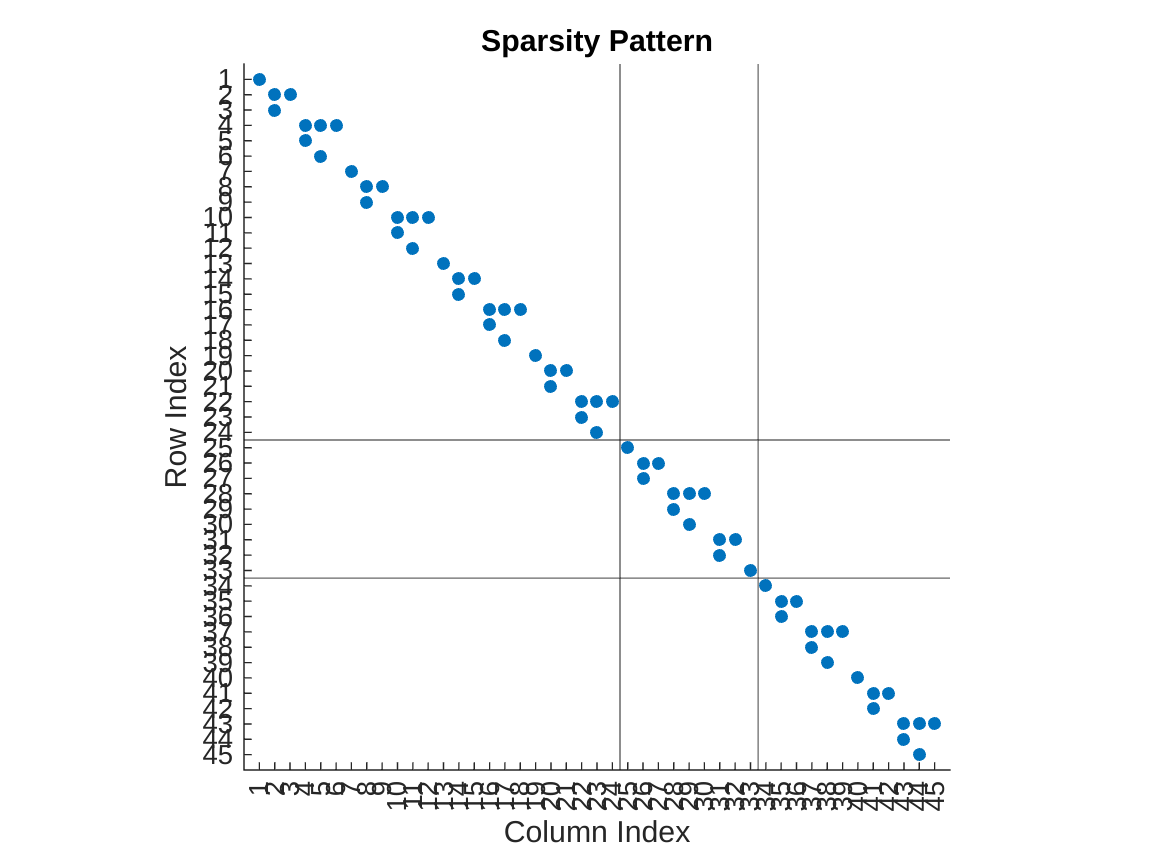

spsty_idx_set(Phiu.A,I_u,I_u)

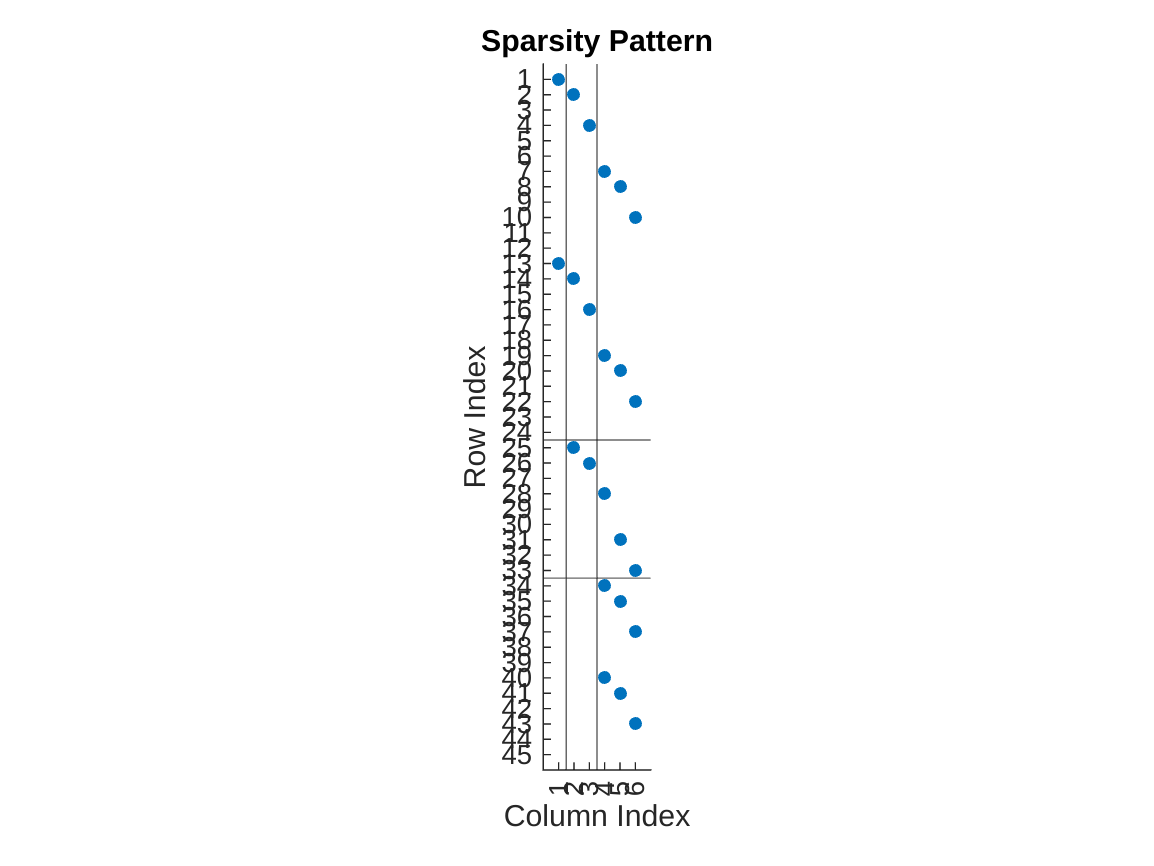

spsty_idx_set(Phiu.B,I_u,partition_x)

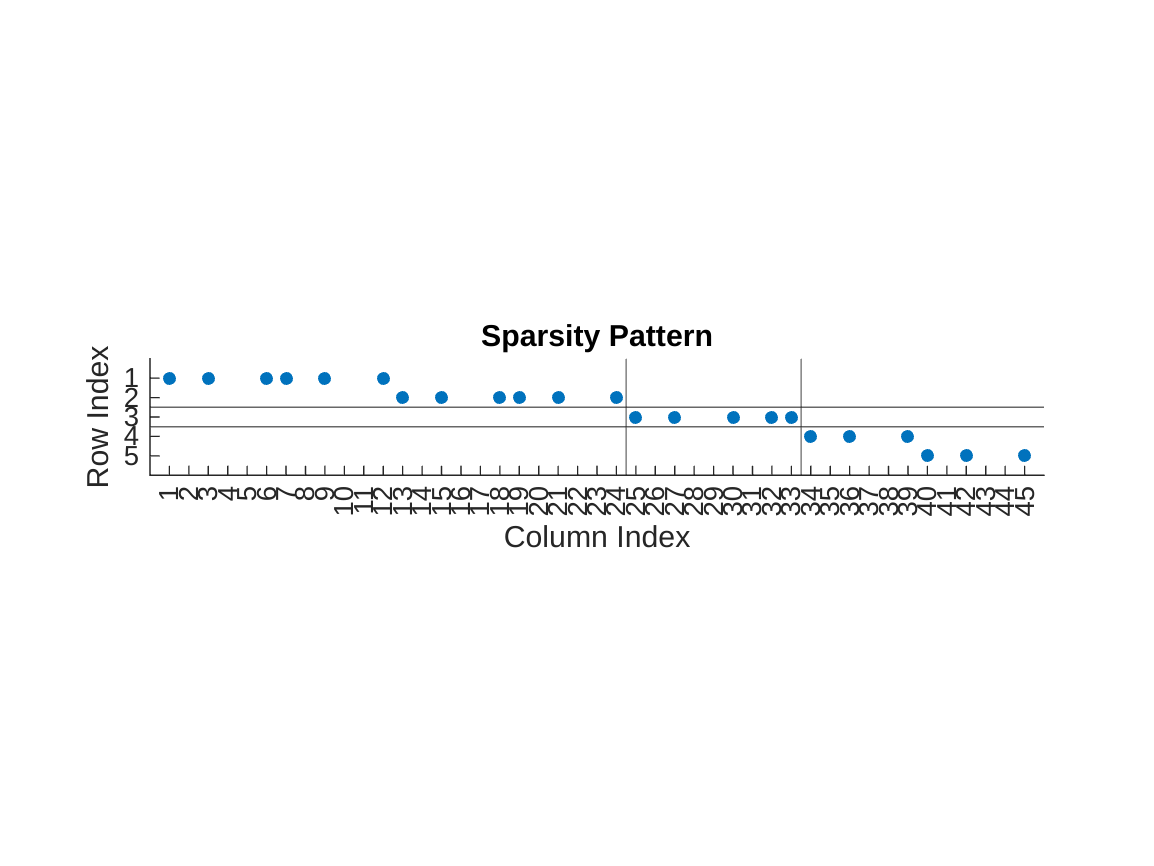

spsty_idx_set(Phiu.C,partition_u,I_u)

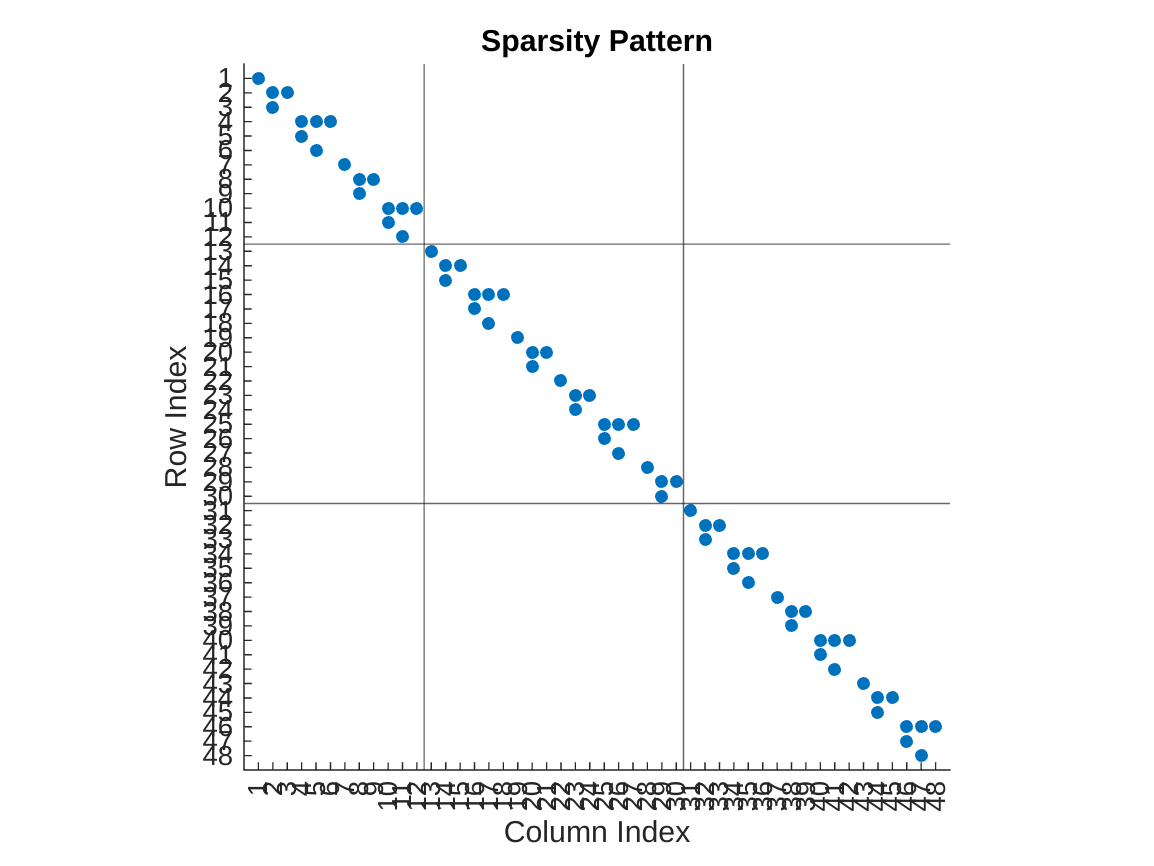

spsty_idx_set(Phix.A,I_x,I_x)

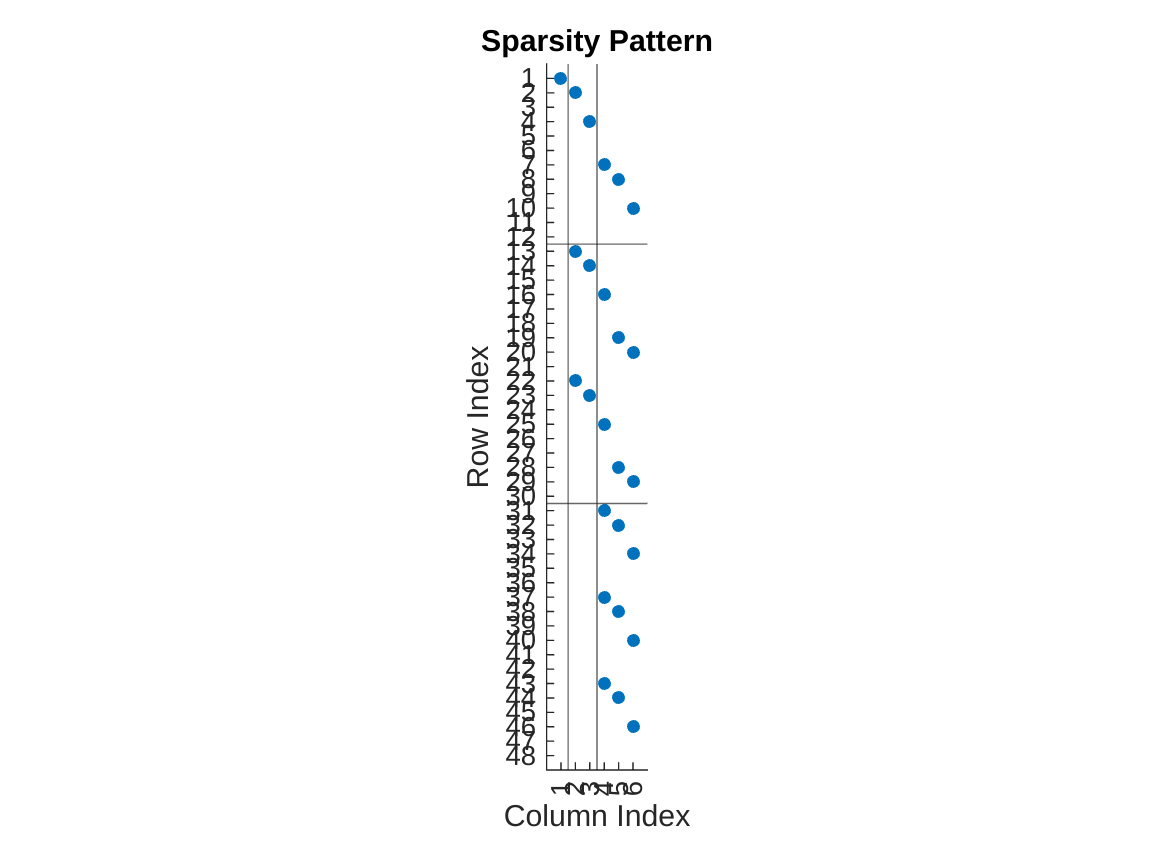

spsty_idx_set(Phix.B,I_x,partition_x)

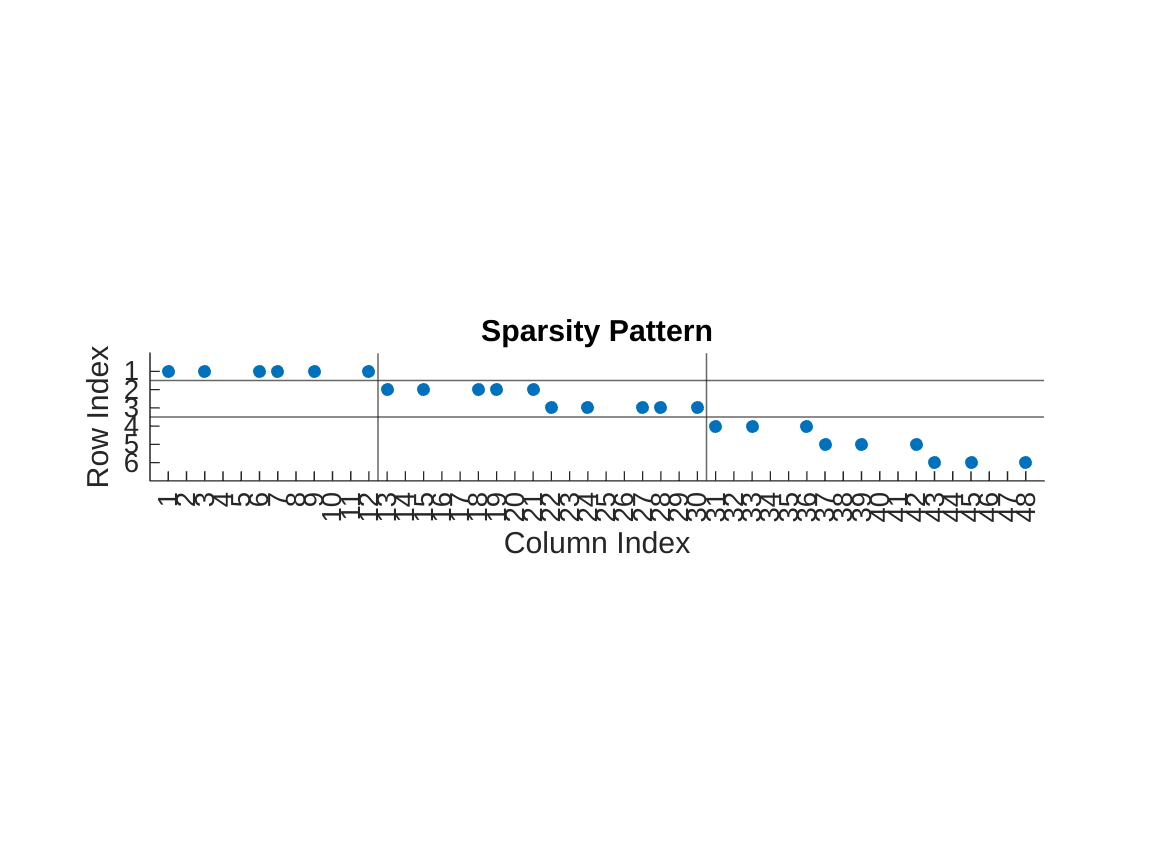

spsty_idx_set(Phix.C,partition_x,I_x)

Indeed we see that the $A$ matrices are diagonal (though they're actually allowed to be triangular), the $B$ matrices are triangular and the $C$ matrices are diagonal.

## Next steps

- Trivial step 1: go from structured realization of $\Phi^x$ and $\Phi^u$ to unstructured realization of $K=\Phi^u(\Phi^x)^{-1}$. The realization of $K$ is given in $\texttt{example1.mlx}$

- Trivial step 2: go from unstructured realization of $K$ and similarity transformation $T$ to structured realization of $K$. The way to apply this transformation to get a structured realization of $K$ is also given in $\texttt{example1.mlx}$

- Test the entire pipeline on the example in this script. This means starting from only the inputs given by line 17, arrive at a structured realization of $K$.